## 1. Import robot model

### 1.1 URDF to rigidbodytree

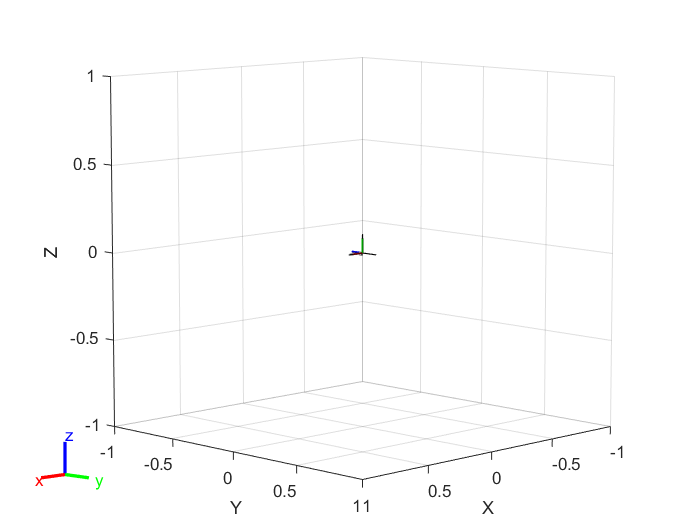

% clc
% clear
% robot = importrobot('Pendulum_SLDASM.urdf');
% show(robot);

% showdetails(robot);

--------------------
Robot: (1 bodies)

 Idx     Body Name     Joint Name     Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------     ----------     ----------     ----------------   ----------------
   1        1_Link        1_Joint       revolute         base_link(0)   
--------------------


### 1.2 URDF to simscape

% smimport('Pendulum_SLDASM.urdf');

## 2. Dynamics parameter identification process

### 2.1 Check origin inertia matrix directly from solidworks

% Theta_sw is inertia matrix get from solidworks 
% tau_sw is torque calculated from solidworks inertia
syms m L_c I_zz Theta_sw tau_sw
m = 14.39*10^(-3);%kg
L_c = 50.59*10^(-3);%m
I_zz = 13822.02*10^(-9);%kg*m2
g = 9.81;%N/kg
Theta_sw = [m*L_c^2+I_zz;m*g*L_c]

Theta_sw =     0.0001
    0.0071


1000*Theta_sw

ans =     0.0507
    7.1416


### 2.2 Retrive data for identification

% Retrive data for identification
StartDataindex = 1000;
EndDataindex = 2000;
step = 10;
numOfData = (EndDataindex-StartDataindex)/step+1

numOfData = 101

% Y and tau
Y = zeros(numOfData,2);
tau = zeros(numOfData,1);
for n=1:1:numOfData
   Y(n,1)=getdatasamples(Joint1Acce,step*(n-1)+StartDataindex);
   Y(n,2)=cos(getdatasamples(Joint1Pos,step*(n-1)+StartDataindex));
   tau(n,1) = getdatasamples(Joint1Torq,step*(n-1)+StartDataindex);
end

### 2.3 Identification result

theta=inv((Y.')*Y)*(Y.')*tau

theta =     0.0000
    0.0071


1000*theta

ans =     0.0457
    7.1382


% Use identified inertia to calculate torque to verify your result
% tau_esti
tau_esti = Y*theta;

### 2.4 Verify the result

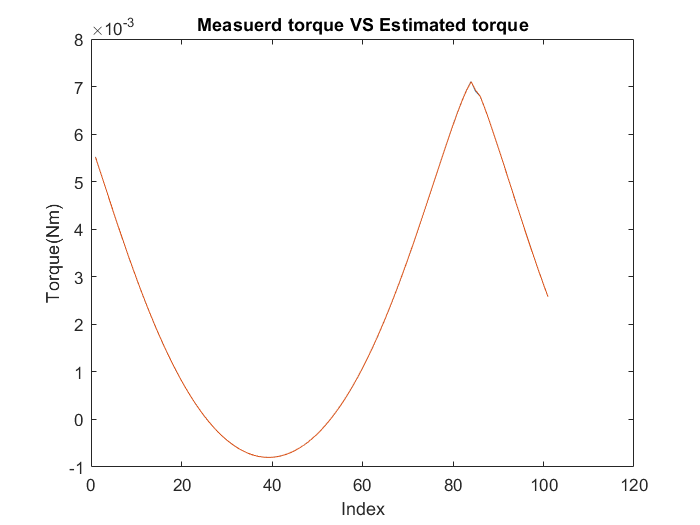

error = tau_esti-tau;
index=1:1:numOfData;
% Measuerd torque VS Estimated torque
plot(index,tau,index,tau_esti)
title('Measuerd torque VS Estimated torque')
xlabel('Index');
ylabel('Torque(Nm)');

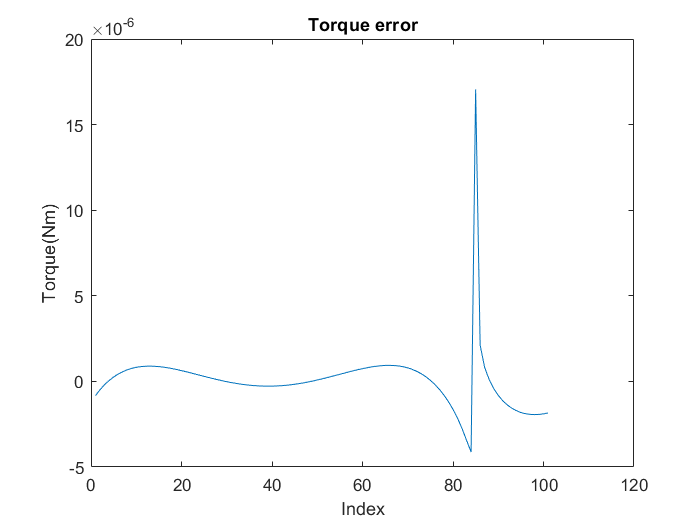

% Error 
plot(error)
title('Torque error');
xlabel('Index');
ylabel('Torque(Nm)');

### 2.5 Some questions

% Even the torque calculated from solidworks inertia is not the same as
% troque measured,why?
tau;
tau_real = Y*Theta_real;
error1 = tau- tau_real;